% AAE 421 EXAM 2 MATLAB CODE 
% TOMOKI KOIKE
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\exam2";

% Problem 1
% Parameters
epsilon = 0.9;
AR = 0.86;
m = 0.003;
S = 0.017;
cD0 = 0.02;
rho = 0.41405;
h = 10000;
cLa = 1.2936;
g = 9.81;

% (a)
% Equilibrium conditions 
he = h;
Ve = 3.7;
gamma = 0;

% Find trim conditions
syms alpha T
cL = cLa * alpha;
L = 0.5*rho*Ve^2*S*cL;
D = 0.5*rho*Ve^2*S*(cD0 + epsilon*cL^2);

eqn1 = 0 == (T - D - m*g*sin(gamma)) / m;
eqn2 = 0 == (L - m*g*cos(gamma)) / m / Ve;
res = solve([eqn1, eqn2], [alpha, T]);

% (b)
alpha_trim = double(res.alpha)

alpha_trim = 0.4722

T_trim = double(res.T)

T_trim = 0.0171

simout = sim("e2_p1_model.slx");
t = simout.tout;
Vsim = simout.vout.signals.values;
gammasim = simout.gammaout.signals.values;
hsim = simout.hout.signals.values;

% Plotting 
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
    subplot(3,1,1)
    plot(t,Vsim)
    grid on; grid minor; box on;
    ylabel('V [m/s]')
    subplot(3,1,2)
    plot(t,gammasim)
    grid on; grid minor; box on;
    ylabel('$\gamma$ [rad]')
    subplot(3,1,3)
    plot(t,hsim)
    grid on; grid minor; box on;
    ylabel('h [m]')
    xlabel('time, [sec]')
    sgtitle('Problem 1 (b) $0\leq t \leq 10$ - T. Koike')
saveas(fig1, fullfile(fdir, "p1_2.png"));

[A, B, C, D] = linmod('e2_p1_model',[Ve;gamma;he],[alpha_trim; T_trim])

A =    -3.0889   -9.8100         0
    1.4332         0         0
         0    3.7000         0


B =   -22.8430  333.3333
    5.6150         0
         0         0


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0
     0     0
     0     0


% Problem 2
clear all; 
zeta = 0.3;
wn = 1.0; 
sd1 = -zeta*wn + wn^2*sqrt(1 - zeta^2)*1j;
sd2 = -zeta*wn - wn^2*sqrt(1 - zeta^2)*1j;
p = [sd1, sd2];

Yb = -19.5;
Yr = -1.3;
Nb = 1.5;
Nr = -0.21;
U0 = 400;

A = [Yb/U0, Yr/U0; Nb, Nr]

A =    -0.0488   -0.0033
    1.5000   -0.2100


B = [1; 1]

B =      1
     1


res = ackermannMethod(A, B, p)

res = struct with fields:
    check: 1
        K: [-0.3401 0.6813]
       Ad: [2×2 double]
       Qc: [2×2 double]
       DA: [2×2 double]
       Ds: [1 0.6000 1]


res.Ds

ans =     1.0000    0.6000    1.0000


res.DA

ans =     0.9683   -0.0011
    0.5119    0.9132


res.Qc

ans =     1.0000   -0.0520
    1.0000    1.2900


res.Ad

ans =     0.2913   -0.6846
    1.8401   -0.8913


res.K

ans =    -0.3401    0.6813


ans =    -0.3401    0.6813


eig(res.Ad)

ans =   -0.3000 + 0.9539i
  -0.3000 - 0.9539i


% Problem 3
clear all;
zeta = 0.3;
wn = 2.0;
OS = exp(-zeta*pi / sqrt(1 - zeta^2))

OS = 0.3723

tau = 1 / zeta / wn;

tau = 1.6667

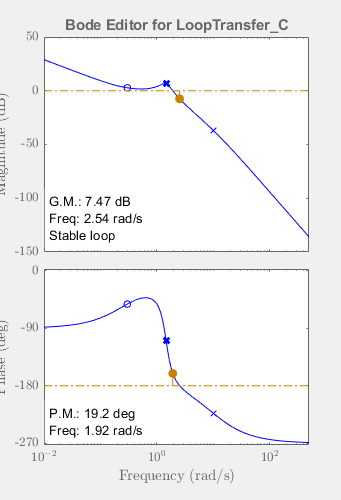

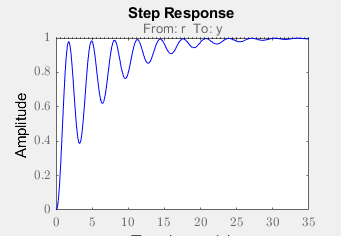

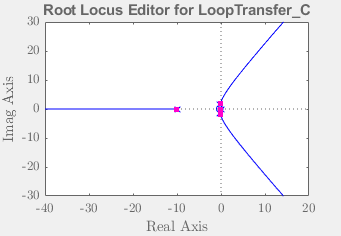

num = conv([0, 10], 2.0*[1, 0.3]);
den = conv([1, 10], [1, 0.65, 2.15]);
den = conv(den, [1, 0]);
sys = tf(num, den);
s = tf("s");
C2 = 1*s;
controlSystemDesigner(sys);

num = conv([0, 10], 2.0*[1, 0.3]);
den = conv([1, 10], [1, 0.65, 2.15]);
Krg = 0.392;
Kvg = 0.76561;
Ginner = tf(num, den);
inner = feedback(Ginner, Krg);
integrator = tf([0, 1], [1, 0]);
Gouter = Kvg * inner * integrator;
sys_tuned = feedback(Gouter, 1)

sys_tuned =
 
                 15.31 s + 4.594
  ---------------------------------------------
  s^4 + 10.65 s^3 + 16.49 s^2 + 39.16 s + 4.594
 
Continuous-time transfer function.



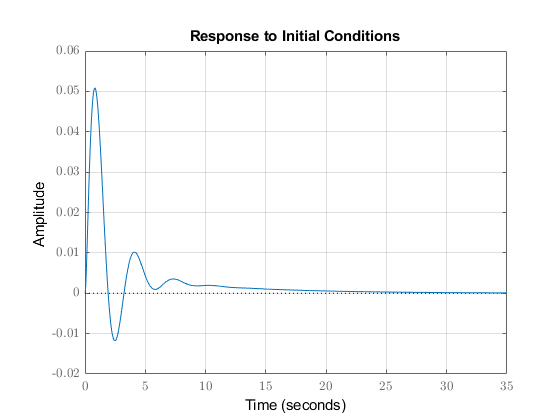

sys_tuned_ss = ss(sys_tuned);
initial(sys_tuned_ss, [deg2rad(5);0;0;0])
grid on; grid minor;

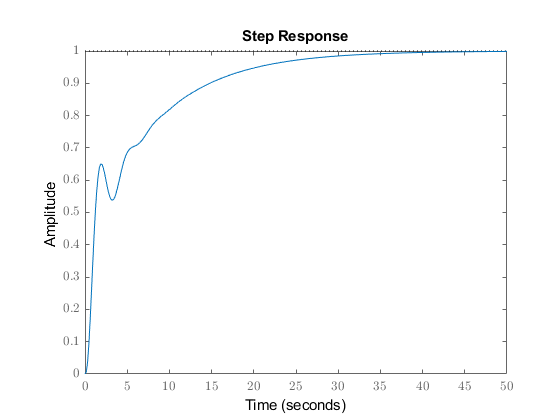

step(sys_tuned)

% Bonus 

clear all; close all; clc;